
data = readtable('retail_sales_dataset.csv');


%overview of data
disp('Data Overview:');

Data Overview:


disp(head(data)); 

    TransactionID       Date       CustomerID       Gender      Age    ProductCategory    Quantity    PricePerUnit    TotalAmount
    _____________    __________    ___________    __________    ___    _______________    ________    ____________    ___________

          1          2023-11-24    {'CUST001'}    {'Male'  }    34     {'Beauty'     }       3             50             150    
          2          2023-02-27    {'CUST002'}    {'Female'}    26     {'Clothing'   }       2            500            1000    
          3          2023-01-13    {'CUST003'}    {'Male'  }    50     {'Electronics'}       1             30              30    
          4          2023-05-21    {'CUST00

disp('Summary:');

Summary:


disp(summary(data));

      TransactionID: [1×1 struct]
               Date: [1×1 struct]
         CustomerID: [1×1 struct]
             Gender: [1×1 struct]
                Age: [1×1 struct]
    ProductCategory: [1×1 struct]
           Quantity: [1×1 struct]
       PricePerUnit: [1×1 struct]
        TotalAmount: [1×1 struct]



disp('Data Size:');

Data Size:


disp(size(data)); 

        1000           9




%checking missing vlues
disp('Missing Values:');

Missing Values:


missingData = sum(ismissing(data));
disp(missingData);

     0     0     0     0     0     0     0     0     0



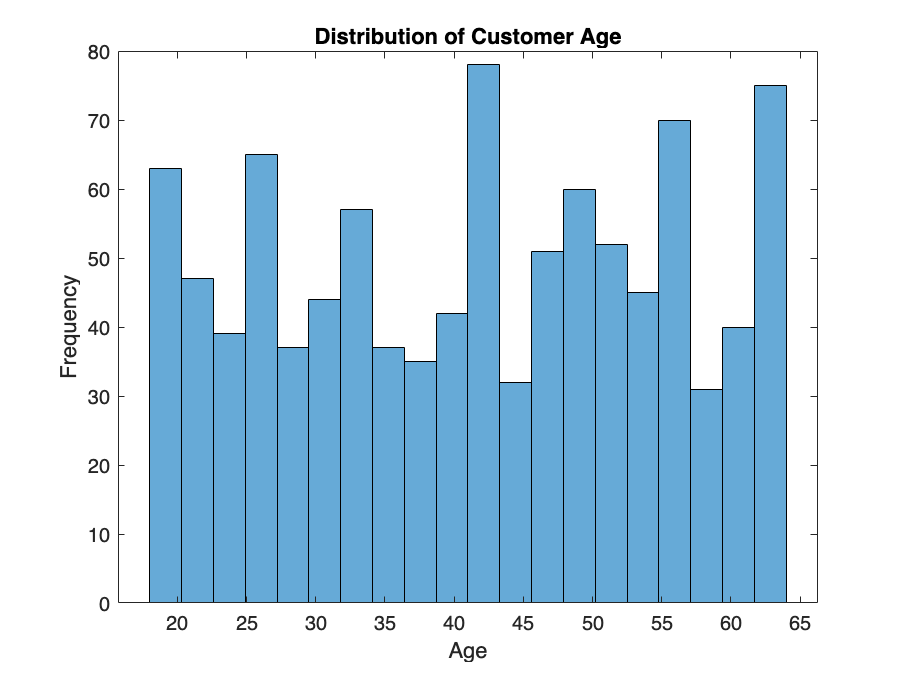


%frequency of age group 
figure;
histogram(data.Age, 20); 
title('Distribution of Customer Age');
xlabel('Age');
ylabel('Frequency');

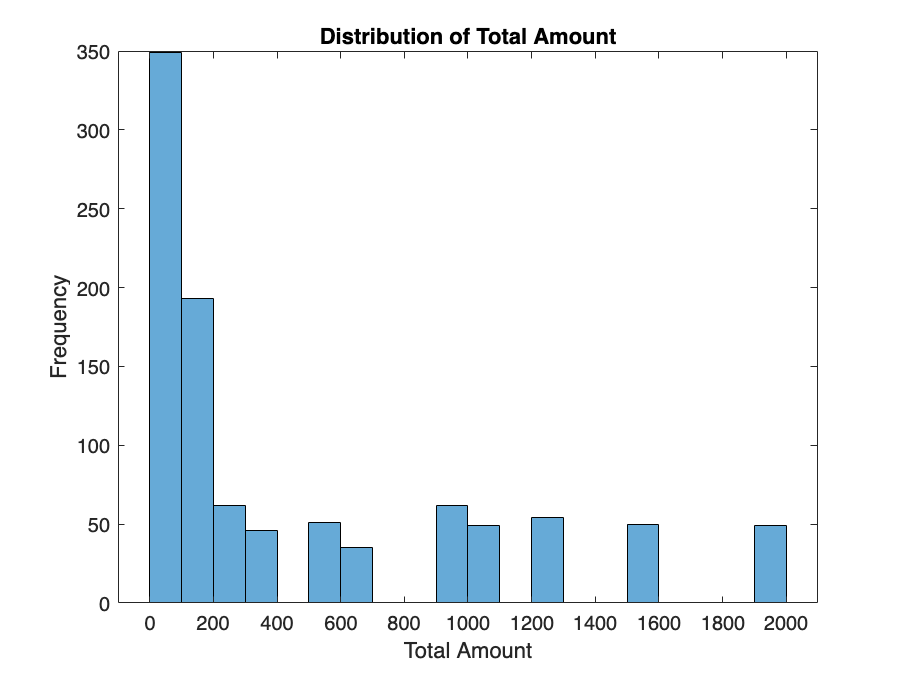


%frequency of total amount
figure;
histogram(data.TotalAmount, 20); 
title('Distribution of Total Amount');
xlabel('Total Amount');
ylabel('Frequency');

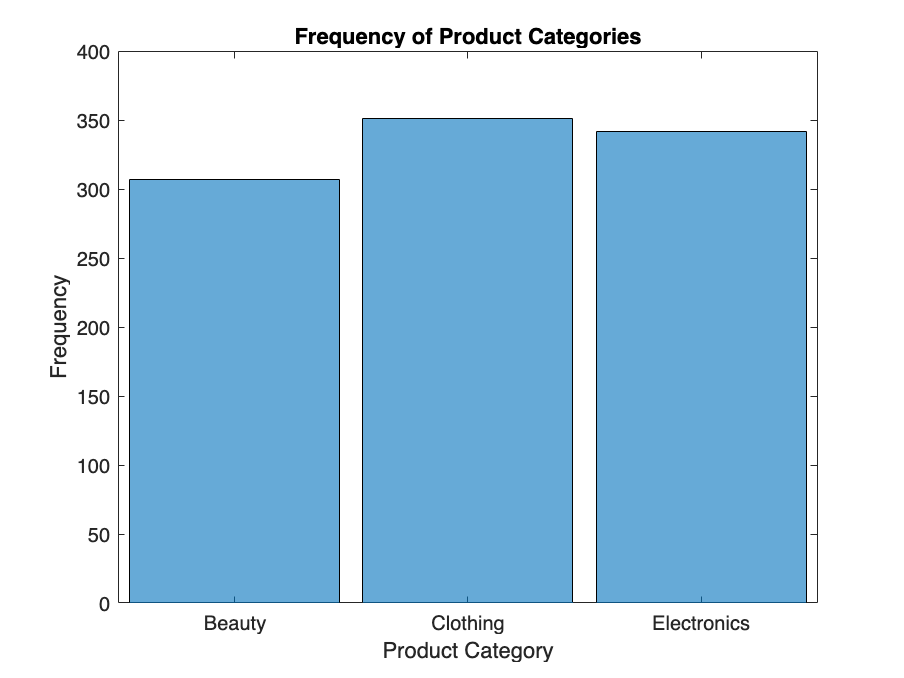


%frequency of Product Category
figure;
productCategories = categorical(data.ProductCategory); % Convert to categorical
histogram(productCategories);
title('Frequency of Product Categories');
xlabel('Product Category');
ylabel('Frequency');

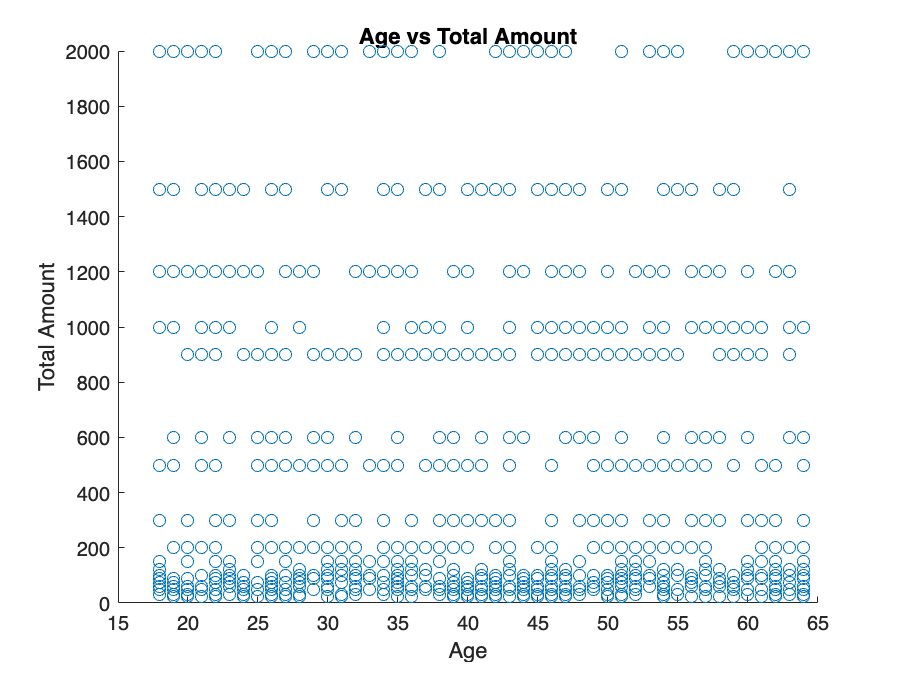


%Relation b/w Age and TotalAmount
figure;
scatter(data.Age, data.TotalAmount); 
title('Age vs Total Amount');
xlabel('Age');
ylabel('Total Amount');

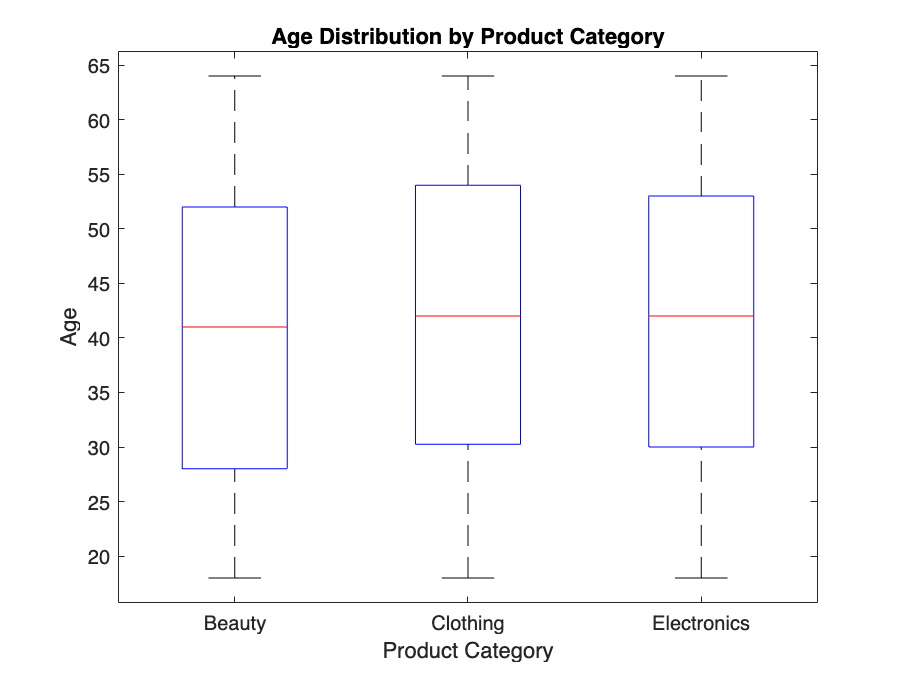


%Relation b/w Age and Product Category
figure;
boxplot(data.Age, productCategories);
title('Age Distribution by Product Category');
xlabel('Product Category');
ylabel('Age');

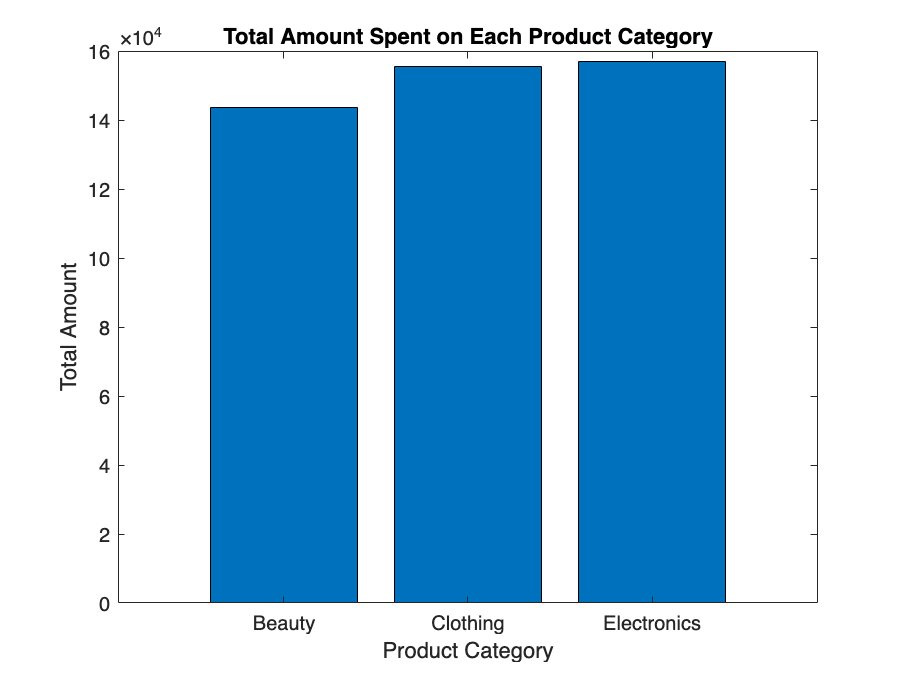



% Total amount spent for each product category
totalAmountByCategory = groupsummary(data, 'ProductCategory', 'sum', 'TotalAmount');

figure;
bar(totalAmountByCategory.ProductCategory, totalAmountByCategory.sum_TotalAmount);
title('Total Amount Spent on Each Product Category');
xlabel('Product Category');
ylabel('Total Amount');

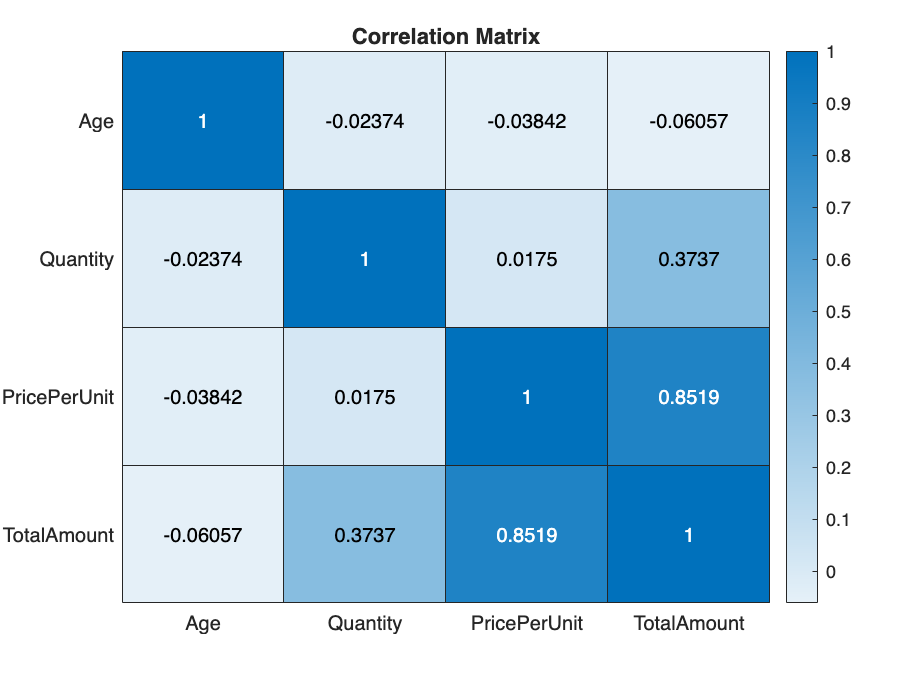




%Correlation Matrix
numericColumns = {'Age', 'Quantity', 'PricePerUnit', 'TotalAmount'};
corrMatrix = corr(table2array(data(:, numericColumns)), 'rows', 'pairwise');
figure;
heatmap(numericColumns, numericColumns, corrMatrix);
title('Correlation Matrix');

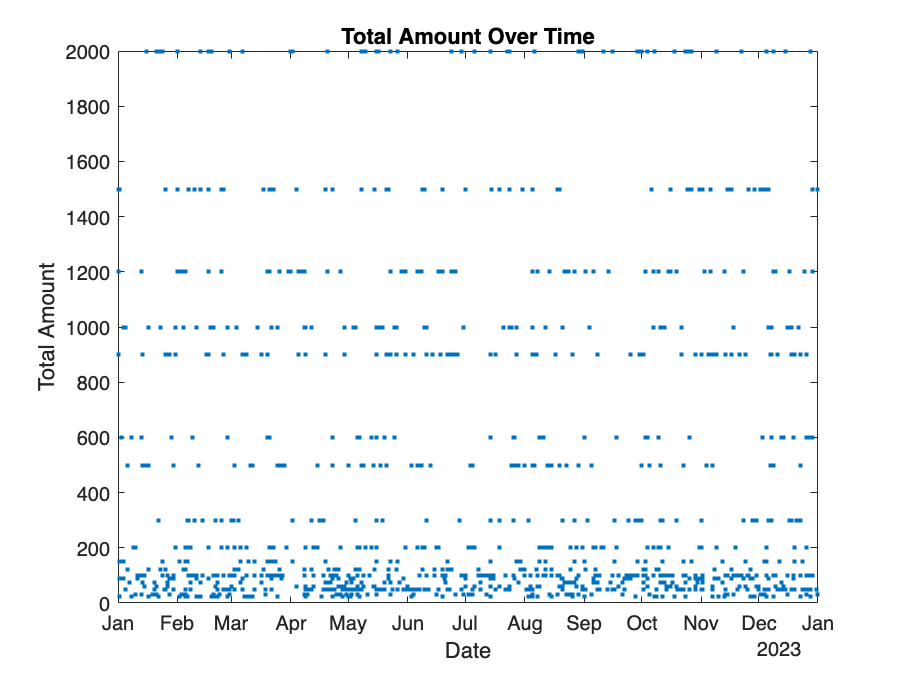



%Time series Analysis
data.Date = datetime(data.Date, 'InputFormat', 'yyyy-MM-dd'); 
figure;
plot(data.Date, data.TotalAmount, '.'); 
title('Total Amount Over Time');
xlabel('Date');
ylabel('Total Amount');

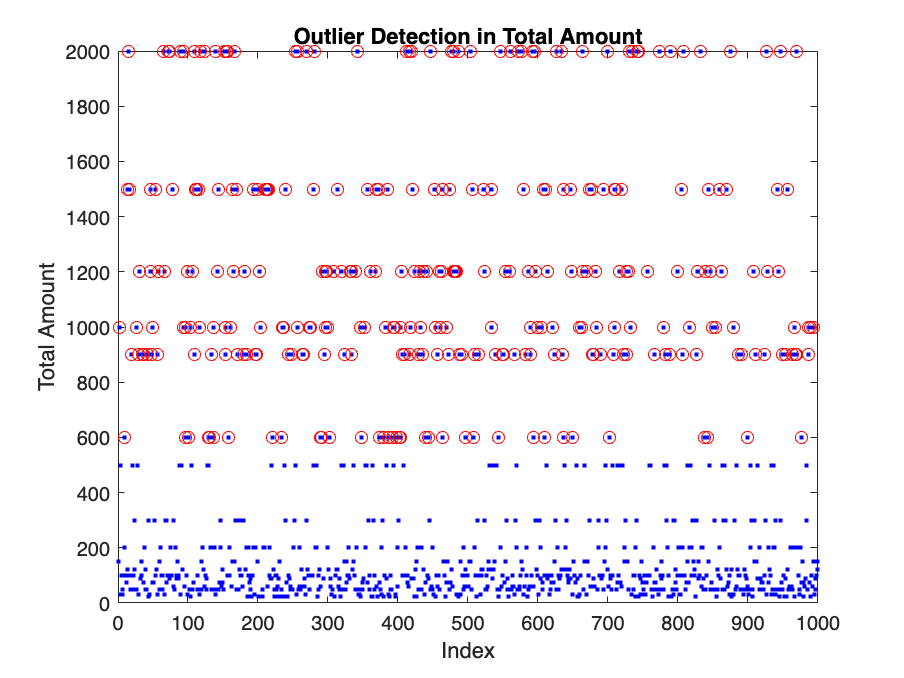




figure;
isOutlier = isoutlier(data.TotalAmount); 
plot(data.TotalAmount, 'b.'); 
hold on;
plot(find(isOutlier), data.TotalAmount(isOutlier), 'ro'); 
title('Outlier Detection in Total Amount');
xlabel('Index');
ylabel('Total Amount');